%------ EULER RL (podobná přesnost jako adaptivní) ---------------
figure(1);
tic
[t,i] = euler(@RL,0,0.01,0,39);
toc

Elapsed time is 0.169290 seconds.


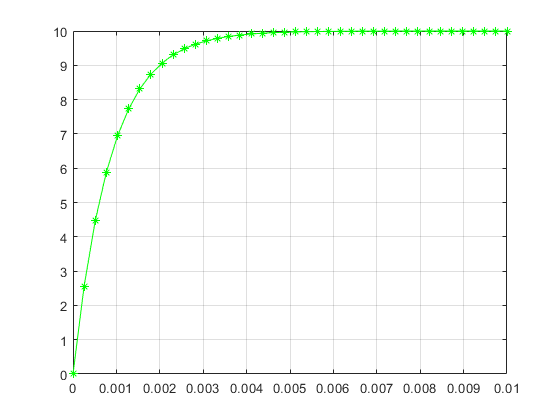

plot(t,i,'g*-');
Legend1{1} = "Euler (40 kroků)";
grid on;
hold on;

%------ EULER RL (stejný počet kroků jako adaptivní) --------------
tic
[t,i] = euler(@RL,0,0.01,0,14);
toc

Elapsed time is 0.008247 seconds.


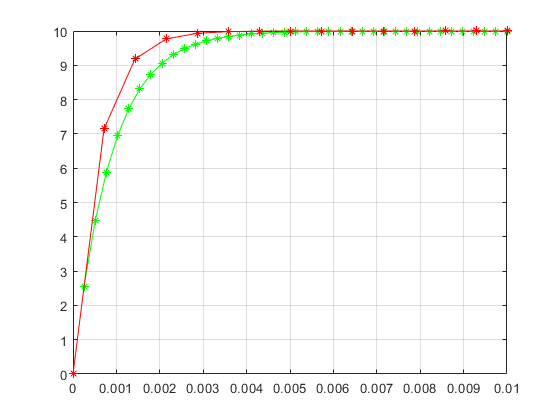

plot(t,i,'r*-');

Legend1{2} = "Euler (15 kroků)";

%------ ADAPTIVNI EULER RL ---------------------------------------
tic
[t,i] = aeuler_moje_puvodni(@RL,0,0.01,0,0.05,0.1);
toc

Elapsed time is 0.030884 seconds.


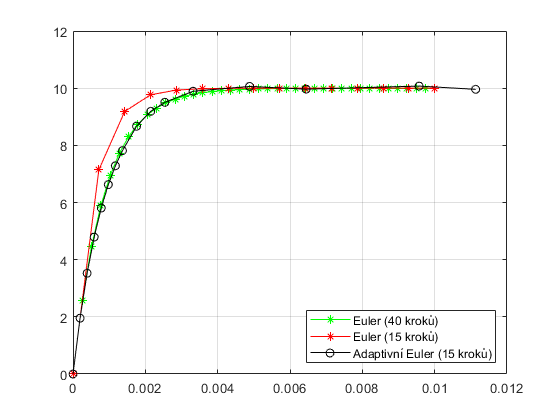

plot(t,i,'ko-');
Legend1{3} = "Adaptivní Euler (15 kroků)";
legend(Legend1,'Location','southeast')
hold off;

%------ EULER RLC -------------------------------------------------
figure(2);
tic
[t,ui] = euler(@RLC,0,0.01,[0 0],50000);
toc

Elapsed time is 0.947112 seconds.


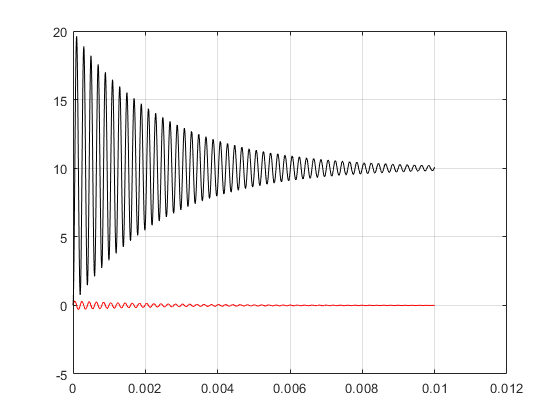

i = ui(:,1);
u = ui(:,2);
plot(t,i,'r');
Legend2{1} = "Euler proud";
grid on;
hold on;
plot(t,u,'k');

Legend2{2} = "Euler napětí";

%------ ADAPTIVNI EULER RLC ----------------------------------------
tic
[t,ui] = aeuler_moje_puvodni(@RLC,0,0.01,[0 0],0.001,0.00005);
toc

Elapsed time is 3.137718 seconds.


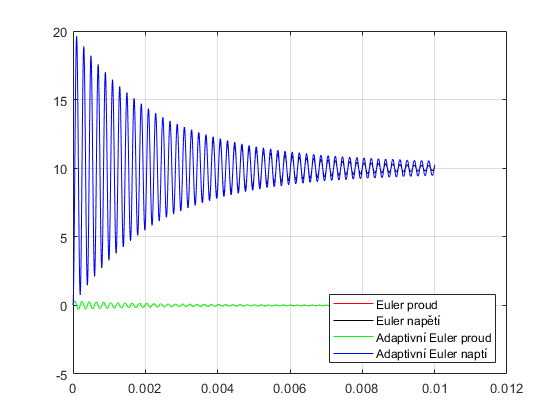

i = ui(:,1);
u = ui(:,2);
plot(t,i,'g');
Legend2{3} = "Adaptivní Euler proud";
plot(t,u,'b');
Legend2{4} = "Adaptivní Euler naptí";
legend(Legend2,'Location','southeast')
hold off;